% r = 1; % step sign
% numo = [1, 2]; deno = [1 3 6 2];
% numh = 3; denh = 1;
% [num, den] = feedback(numo, deno, numh, denh);
% [A B C D] = tf2ss(num, den);
A = [0 1 0; 0 0 1; -6 -11 -6];
B = [0; 11; -60];
C = [1 0 0];
D = 0

D = 0

r = 1

r = 1

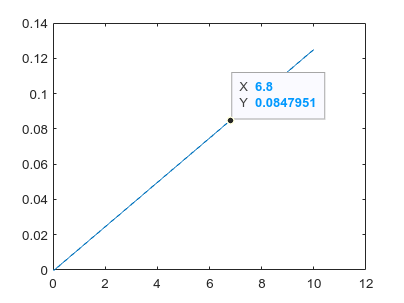

TF = 10; % all time
h = 0.05; % step time
x = [zeros(length(A), 1)]; y = 0; t = 0;

for i = 1 : TF/h
    r = t(i);
    k1 = A * x + B * r;
    k2 = A * (x + h * k1 / 2) + B * r;
    k3 = A * (x + h * k2 / 2) + B * r;
    k4 = A * (x + h * k3) + B * r;
    x = x + h * (k1 + 2 * k2 + 2 * k3 + k4) / 6;
    

    y = [y ; C * x]; 
    t = [t ; t(i) + h];
end
plot(t, y);

function y = func_RK4_ss(A, B, C, x, r, h)
    k1 = A * x + B * r;
    k2 = A * (x + h * k1 / 2) + B * r;
    k3 = A * (x + h * k2 / 2) + B * r;
    k4 = A * (x + h * k3) + B * r;
    x = x + h * (k1 + 2 * k2 + 2 * k3 + k4) / 6;
    y = C * x;
end